clc;
clear;
s = tf("s");
G = 165 / ((s+1)*(s+2)*(s+10)) % trocar pelo do exercicio 


G =
 
            165
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.
Model Properties


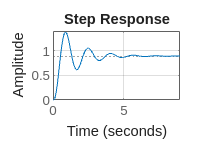


G_mf=feedback(G,1);
step(G_mf)
grid on;


Mp = 0.05; % passado no exercicio que Mp deve ser 5%
ts = 2; % passado no exercicio que ts deve ser 2s

zeta = -log(Mp)/(sqrt(log(Mp)^2+3.14^2));
omega_n = 4 / (zeta*ts);
sigma = zeta*omega_n;
parte_real = -zeta*omega_n;
parte_imag = omega_n*sqrt(1 - zeta^2);

fprintf("Zeta: %.3f / Omega_n: %.3f", zeta, omega_n);

Zeta: 0.690 / Omega_n: 2.897

fprintf("Polos do controlador: %.3f +- %.3f", parte_real, parte_imag);

Polos do controlador: -2.000 +- 2.096


% Controlador PD
s1 = parte_real + parte_imag*1i

s1 = -2.0000 + 2.0963i


aux_eq = 165/((s1+1)*(s1+2)*(s1+10)); % trocar pelo do exercicio 

contribuicao_angular = 180 - rad2deg(angle(aux_eq))

contribuicao_angular = 40.1860


x = parte_imag / tan(deg2rad(contribuicao_angular));
zero_controlador_PD = sigma + x;
fprintf("Zero do controlador: -%.3f", zero_controlador_PD);

Zero do controlador: -4.482

    
Td = 1/zero_controlador_PD

Td = 0.2231


syms Kc 
eq_Kc = abs( Kc * Td * (s1+zero_controlador_PD) * aux_eq) == 1;
Kc = double(solve(eq_Kc, Kc))

Kc = 0.3367

K = Kc * Td

K = 0.0751


% Controlador PI
zero_controlador_PI = -(-0.1) % Considerando que o zero do termo (s+z2) esteja em s=−0,1

zero_controlador_PI = 0.1000


% Controlador PID
% expessão a baixo vem de K * (s+z1) * ((s+z2)/s) conforme o enunciado
G_c_PID_sem_K = (s^2 + (zero_controlador_PI+zero_controlador_PD) * s + zero_controlador_PD*zero_controlador_PI)/s


G_c_PID_sem_K =
 
  s^2 + 4.582 s + 0.4482
  ----------------------
            s
 
Continuous-time transfer function.
Model Properties


G_c_PID_com_K = K * G_c_PID_sem_K


G_c_PID_com_K =
 
  0.07512 s^2 + 0.3442 s + 0.03367
  --------------------------------
                 s
 
Continuous-time transfer function.
Model Properties



Gmfc=feedback(G_c_PID_com_K * G,1)


Gmfc =
 
         12.39 s^2 + 56.79 s + 5.555
  ------------------------------------------
  s^4 + 13 s^3 + 44.39 s^2 + 76.79 s + 5.555
 
Continuous-time transfer function.
Model Properties


poles = pole(Gmfc);
poles_imag_non_zero = poles(imag(poles) ~= 0)

poles_imag_non_zero =   -1.9564 + 2.0808i
  -1.9564 - 2.0808i


pole1 = poles_imag_non_zero(1);

syms zeta omega_n
eq1 = real(pole1) == -zeta*omega_n;
eq2 = imag(pole1) == omega_n*sqrt(1 - zeta^2);
sol = solve([eq1, eq2], [zeta, omega_n]);
new_zeta = double(sol.zeta);
new_omega_n = double(sol.omega_n);

Mp_teorico = exp(1)^(-new_zeta*pi/(sqrt(1-new_zeta^2))) * 100

Mp_teorico = 5.2141


syms Ts
eq_Ts = new_omega_n == 4 / (new_zeta*Ts);
Ts_teorico = double(solve(eq_Ts, Ts))

Ts_teorico = 2.0446